# 2DOF Linear Motion

Solution of 2dof linear system Under base vibration u

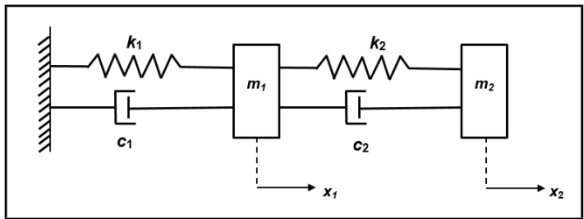

clearvars

## System

f_1 = 700; %[Hz]
m_1 = 2.5; %[kg]
f_2 = 75; %[Hz]
m_2 = 3.5; %[kg]
zeta = 0.02;

## Symbolic

syms m k c x xd xdd [2 1] real
syms u ud real

### Lagrange

T = 1/2*m1*xd1'*xd1 + 1/2*m2*xd2'*xd2;
V = 1/2*k1*(x1-u)*(x1-u) + 1/2*k2*(x2-x1)*(x2-x1);
D = 1/2*c1*(xd1 - ud)'*(xd1 - ud)+ 1/2*c2*(xd2-xd1)'*(xd2-xd1);

L = T - V + D;

dT_dq = gradient(T,x);
dV_dq = gradient(V,x);
dT_dqd = gradient(T, xd);
ddt_dT_dqd = jacobian(dT_dqd, x)*xd + jacobian(dT_dqd, xd)*xdd;
dD_dqd = gradient(D, xd);

eoms = simplify(ddt_dT_dqd - dT_dq + dV_dq + dD_dqd );

### Matrix Form


$$[M]\ddot{x}+[C]\dot{x} + [K]x = [D] \left[ \matrix{u \cr \dot{u}} \right]$$


M_expr = jacobian(eoms, xdd);
C_expr = jacobian(eoms, xd);
K_expr = jacobian(eoms, x);
D_expr = -jacobian(eoms, [u;ud]);

### Going Numeric

k_1 = m_1*(2*pi*f_1)^2;
k_2 = m_2*(2*pi*f_2)^2;
c_1 = m_1*2*zeta*(2*pi*f_1);
c_2 = m_2*2*zeta*(2*pi*f_2);

eoms_Vars = {m1, m2, k1, k2, c1, c2};
eoms_values = {m_1, m_2, k_1, k_2, c_1, c_2};

M = double(subs(M_expr, eoms_Vars, eoms_values));
C = double(subs(C_expr, eoms_Vars, eoms_values));
K = double(subs(K_expr, eoms_Vars, eoms_values));
D = double(subs(D_expr, eoms_Vars, eoms_values));

% M = M_expr;
% C = C_expr;
% K = K_expr;
% D = D_expr;

### Modal Notation


$$[M']\ddot{q}+[C']\dot{q} + [K']q = [D'] \left[ \matrix{u \cr \dot{u}} \right]$$



$$[M', K', C'] \equiv \Phi^T\cdot[M, K, C]\cdot[\Phi];\quad [D'] \equiv\Phi^T \cdot[D]; \\
[\Phi, \omega^2] \equiv eig(M^{-1}\cdot K); \quad \vec{x} = \Phi \cdot \vec{q}$$


[Phi,eVals] = eig(pinv(M)*K);
w_nn = (sqrt(diag(eVals)));
f_nn = w_nn/(2*pi);

M_ = Phi'*M*Phi;
K_ = Phi'*K*Phi;
C_ = 2*zeta*diag(w_nn)*M_;
D_ = Phi'*D;

### Modal TF

TF_u2q1 = tf([D_(1,2) D_(1,1)],[M_(1,1) C_(1,1) K_(1,1)]);
TF_u2q2 = tf([D_(2,2) D_(2,1)],[M_(2,2) C_(2,2) K_(2,2)]);

### Physical TF

TF_u2x1 = minreal(Phi(1,1)*TF_u2q1 + Phi(1,2)*TF_u2q2);
TF_u2x1.InputName = 'U';
TF_u2x1.OutputName = 'X1';
TF_u2x1.Name = 'TF_u2x1';
TF_u2x2 = minreal(Phi(2,1)*TF_u2q1 + Phi(2,2)*TF_u2q2);
TF_u2x2.InputName = 'U';
TF_u2x2.OutputName = 'X2';
TF_u2x2.Name = 'TF_u2x2';

### Physical TF - 1DOF

TF_u2x1_1dof = tf([c_1 k_1],[m_1 c_1 k_1]);
TF_u2x1_1dof.InputName = 'U';
TF_u2x1_1dof.OutputName = 'X1';
TF_u2x1_1dof.Name = 'TF_u2x1_1DOF';
TF_u2x2_1dof = tf([c_2 k_2],[m_2 c_2 k_2]);
TF_u2x2_1dof.InputName = 'U';
TF_u2x2_1dof.OutputName = 'X2';
TF_u2x2_1dof.Name = 'TF_u2x2_1DOF';

## Solution

### Transfer Functions

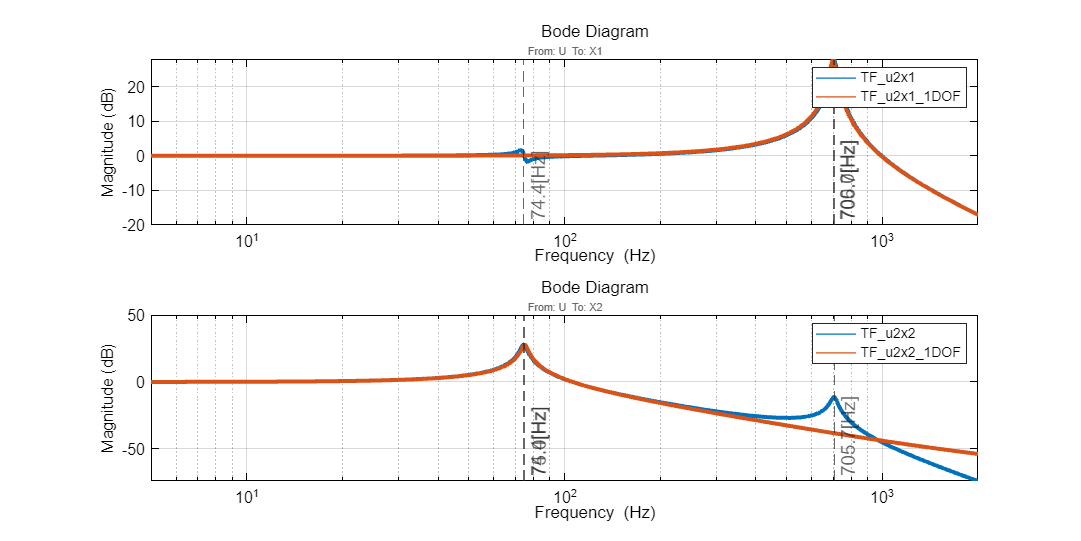

figure('Name','physical trasnfer functions', 'Position',[0 0 1200 600])

f_plot = [5:1:2000];
w_plot = f_plot*2*pi;


[opt_time, opt_bode, opt_nichols] = setPlots;
opt_bode.PhaseVisible = 'off';
opt_bode.XLim = [5 2000];

ax1 = subplot(211);
bodeplot(TF_u2x1, TF_u2x1_1dof, opt_bode)
xline1labels = {sprintf('%.1f[Hz]', f_1), sprintf('%.1f[Hz]',f_nn(1)), sprintf('%.1f[Hz]', f_nn(2))};
xline(ax1, [f_1 f_nn(1) f_nn(2)], '--', xline1labels, 'LabelVerticalAlignment','bottom', 'Fontsize', 14, 'HandleVisibility', 'off');

ax2 = subplot(212);
bodeplot(TF_u2x2, TF_u2x2_1dof, opt_bode)
xline2labels = {sprintf('%.1f[Hz]', f_2), sprintf('%.1f[Hz]',f_nn(1)), sprintf('%.1f[Hz]', f_nn(2))};
xline(ax2, [f_2 f_nn(1) f_nn(2)], '--', xline2labels, 'LabelVerticalAlignment','bottom', 'Fontsize', 14,'HandleVisibility', 'off');

ax = findobj(gcf, 'type', 'axes', '-and', {'Visible', 'on'});

for i = 1:numel(ax)
    legend(ax(i), 'show', 'Location', 'northeast', 'ItemHitFcn', @clickLegendToHide)
end

set_linewidth_ctrl(3)
linkaxes([ax1 ax2], 'x')